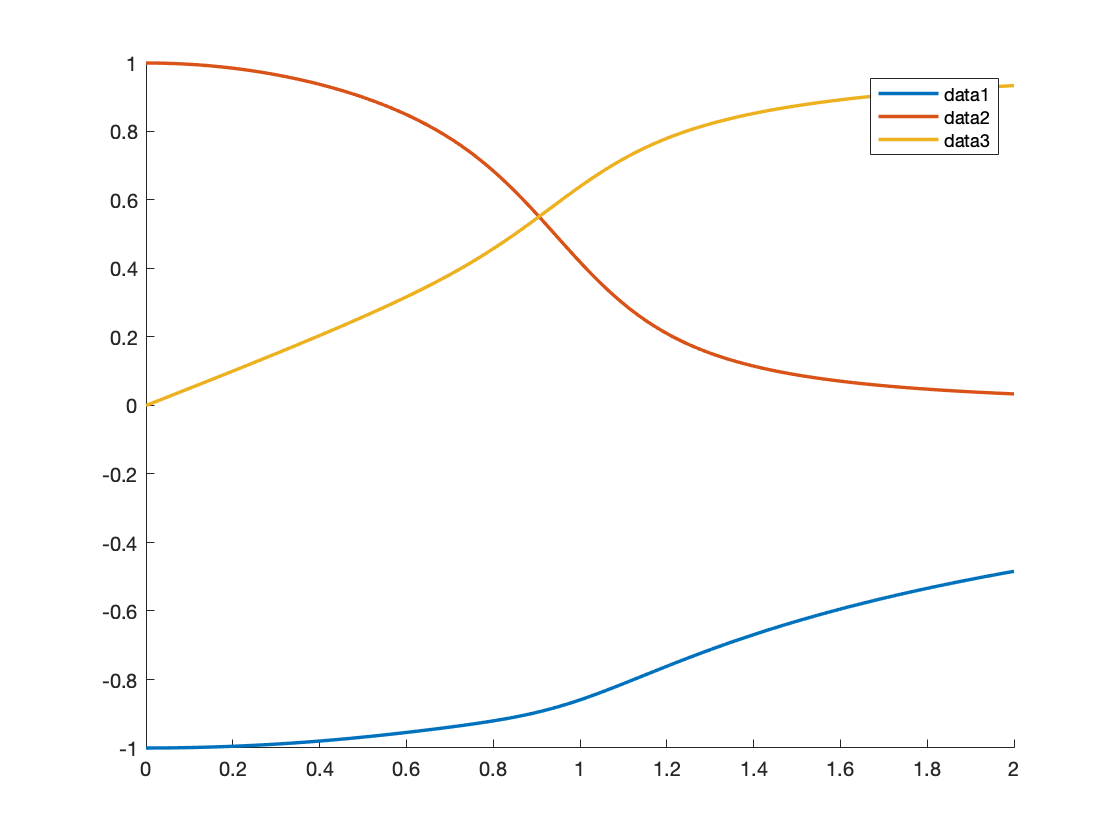

N = 10;
g = 3;

gset = linspace(0,2,100);
YZs = zeros(1,length(gset));
ZZs = zeros(1,length(gset));
Xs = zeros(1,length(gset));
Ms = zeros(3,3,length(gset));
eMs = zeros(3,length(gset));

for i = 1:length(gset)
    g = gset(i);
    [corYZ,corZZ,corX] = cor(N,g);
    corZZ = 2*corZZ;
    corYZ = 2*corYZ;
    YZs(i) = corYZ;
    ZZs(i) = corZZ;
    Xs(i) = corX;
    % Hessian values
    Ms(1,1,i) = -corZZ;
    Ms(1,2,i) = -1i;
    Ms(2,1,i) = 1i;
    Ms(2,2,i) = -corZZ-corX*g;
    Ms(2,3,i) = 1/2*corYZ+1i*g;
    Ms(3,2,i) = 1/2*corYZ-1i*g;
    Ms(3,3,i) = -corX*g;
    eMs(:,i) = eig(Ms(:,:,i),'vector');
end

figure()
hold on
plot(gset,YZs,gset,ZZs,gset,Xs,"LineWidth",1.7)
legend()

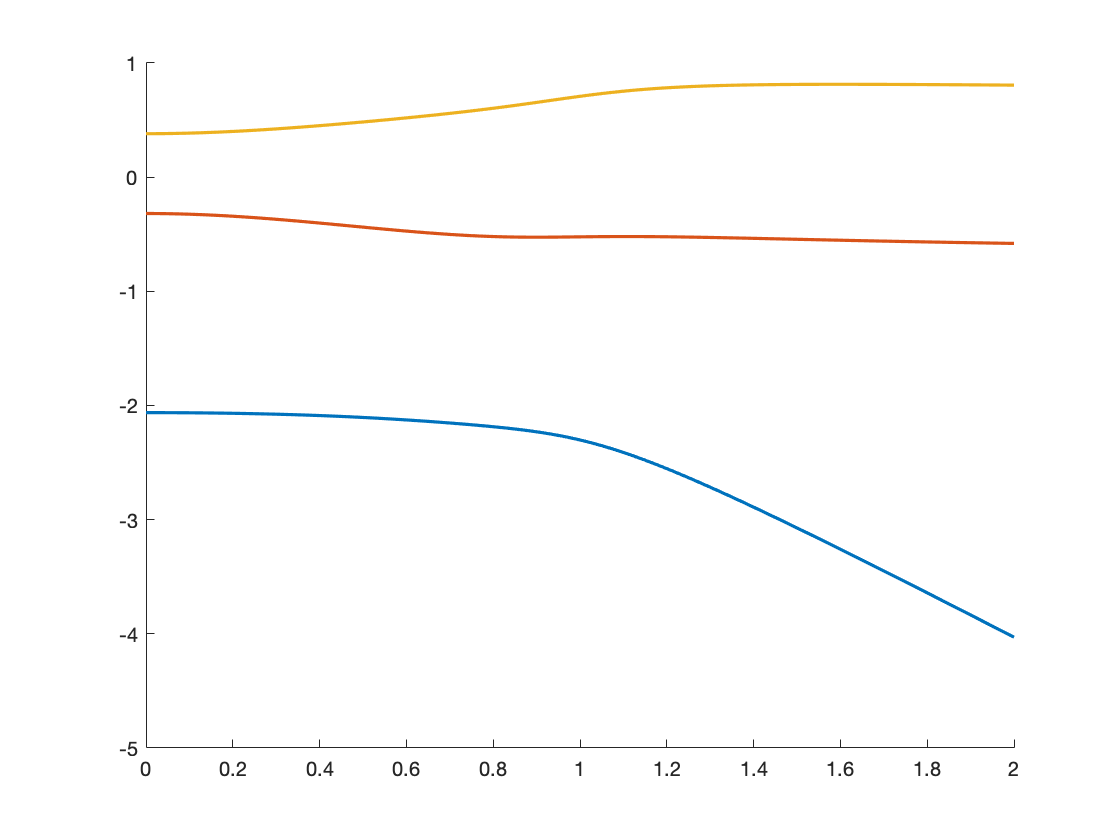




figure()
hold on
for i = 1:3
    plot(gset,eMs(i,:),'LineWidth',1.6);
end
hold off

eMs

eMs =    -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047   -2.1047
   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   -0.4377   

function [corYZ,corZZ,corX] = cor(N,g)
kk = -(N-1)/N*pi:2*pi/N:(N-1)/N*pi;

ep = sqrt(1+g^2-2*g*cos(kk));
cc = (g-cos(kk))./ep;
ss = sin(kk)./ep;

corYZ = 1/N*sum(sin(kk).*(1-cc-ss));
corZZ = 1/N*sum(cos(kk).*(1-cc+ss));
corX = 1/N*sum(cc);
end




